# Elaborato FFT - Analisi del fenomeno climatologico El Nino

Fare l’analisi del fenomeno climatologico El Nino, dovuto ai cambiamenti di pressione nell’Oceano Pacifico. Si analizza il Southern Oscillation Index = differenza di pressione atmosferica tra l’Isola di Pasqua e Darwin(Australia) misurata a livello del mare. Nel file elnino.mat (load –ASCII elnino.mat) vi sono tali valori, misurati ogni mese per 14 anni. Effettuare il grafico del fenomeno, ed il periodogramma eliminando la DC component. Determinare il picco di massima potenza ed il corrispondente indice e periodo.

Carico il file `elnino.mat`

clear all
load -ASCII elnino.mat

Effettuo il grafico del fenomeno:

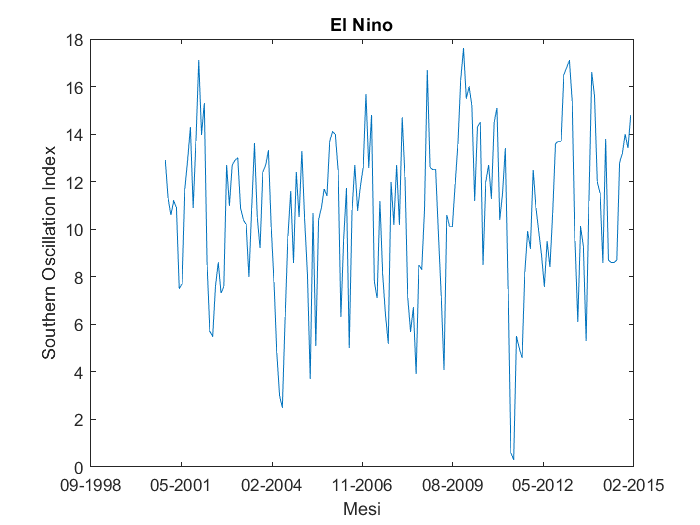

Fc = 1; % Frequenza di campionamento (1 al mese)
n = length(elnino); % Numero di campioni
%t = (1:n); % Istanti di campionamento

startDate = datenum('12-01-2000');
endDate = datenum('12-31-2014');
xData = linspace(startDate,endDate,n);  % Istanti di campionamento
figure();
plot(xData,elnino), title('El Nino'), xlabel('Mesi'), ylabel('Southern Oscillation Index')
datetick('x', 'mm-yyyy','keepticks');

Calcolo la DFT:

Y = fft(elnino);
Y(1) = []; % Elimino la DC component
f = (1:floor(n/2))*Fc/n;

Traccio il grafico del periodogramma:

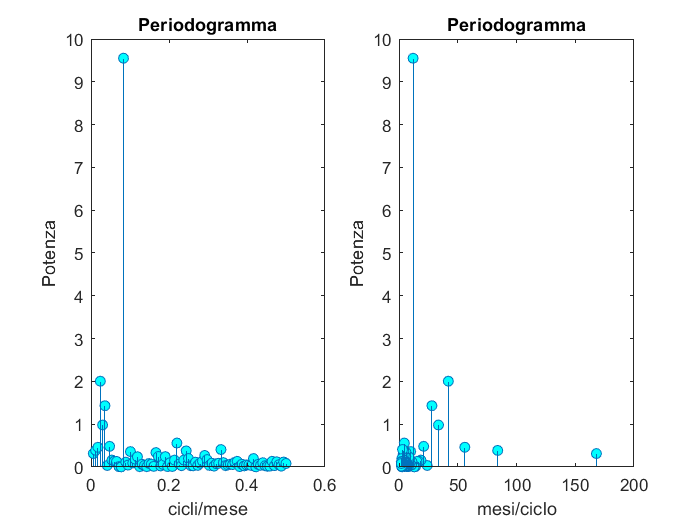

pow = (2*abs(Y(1:floor(n/2))/n)).^2;

figure()
subplot(1,2,1), stem(f, pow,'MarkerFaceColor','c'), title('Periodogramma'), xlabel('cicli/mese'), ylabel('Potenza');
subplot(1,2,2), stem(1./f,pow,'MarkerFaceColor','c'), title('Periodogramma'), xlabel('mesi/ciclo'), ylabel('Potenza');

Visivamente, è immediato rendersi conto che la potenza massima si verifica alla frequenza di circa 0.08, quindi un periodo dominante di 12 anni. Accertiamoci di ciò:

[maxpow, idx] = max(pow);
f_maxpow = f(idx);
t_maxpow = 1/f_maxpow;
fprintf(['Picco di massima potenza: %d\n' ...
    'Periodo del picco: %d\n' ...
    'Indice del picco: %d'], maxpow, t_maxpow, idx);

Picco di massima potenza: 9.550696e+00
Periodo del picco: 12
Indice del picco: 14